# Support Vector Machine (SVM)

DOC: [https://es.mathworks.com/discovery/support-vector-machine.html](https://es.mathworks.com/discovery/support-vector-machine.html)

## Cargamos la factorización y entrenamos SVM 

clc, clear, close all

% Cargamos los datos
U = readmatrix('fact_output/U.csv');
V = readmatrix('fact_output/V.csv');
X = readmatrix('fact_output/X.csv');

% Caracterizamos las clases de forma manual para entrenar de forma
% supervisada
Y = U(:,1) > 0;

% Ajustamos el modelo SVM (pesado de compilar)
cl = fitcsvm(U,Y,"ClassNames",[0, 1]);

## Visualización de los datos y predicción del modelo SVM

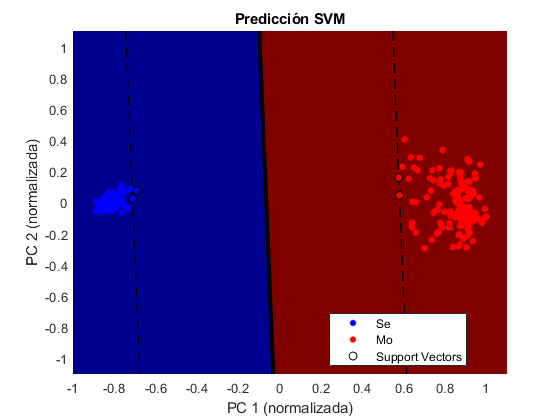

% Generamos un grid para visualizar la predicción
N = 1000;
x_ = linspace(-1.1,1.1,N);
y_ = linspace(-1.1,1.1,N);
[xx,yy] = meshgrid(x_, y_);

% Vectorizamos dichos grids -> serie de puntos
grid_vec = [xx(:),yy(:)];

% Usamos el modelo interpolado para predecir
[Yp, scores] = predict(cl,grid_vec);

% Dibujamos la figura
score_draw = reshape(scores(:,2),size(xx));
Yp_draw    = reshape(Yp         ,size(xx));

figure(1), clf

gscatter(U(:,1), U(:,2), Y, 'br', '.'), hold on
plot(U(cl.IsSupportVector,1), U(cl.IsSupportVector,2),'ko')

contour(xx, yy, score_draw, [ 0 0],'k'  , "LineWidth",3)
contour(xx, yy, score_draw, [-1 1],'--k', "LineWidth",1)

surf(xx,yy,Yp_draw-1), shading interp, colormap jet
caxis([-1 0])
view(2)

legend('Se','Mo','Support Vectors')
title("Predicción SVM")
xlabel("PC 1 (normalizada)")
ylabel("PC 2 (normalizada)")